clc;clear;

## Set derivative gain

g0 = 1;
g1 = 1;
h = 1;

mdlName="triangular_25rules";

## Prepare fuzzy controller

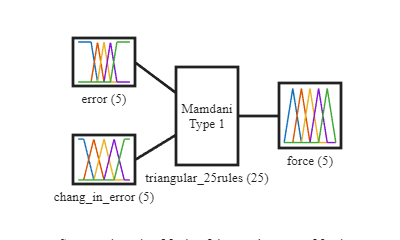

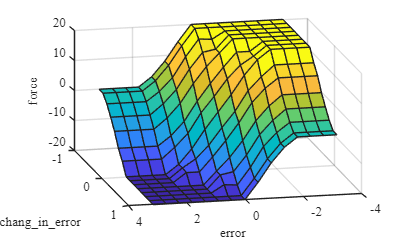

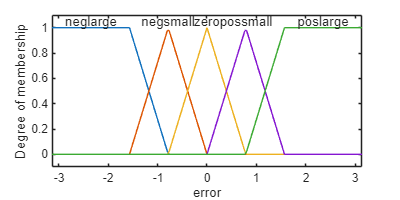

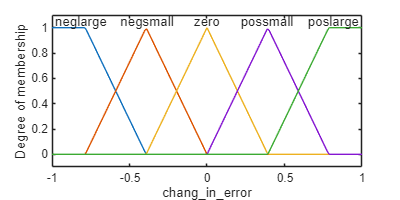

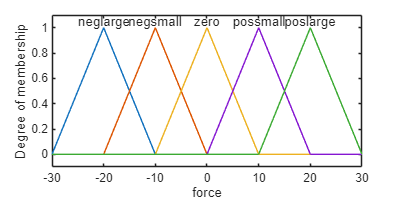

fis = readfis("assets/"+mdlName);
visualizeFIS(fis,mdlName);

## Start Simulink

% open_system("pendulum_system");
[y,u] = simPendulumSystem(fis,g0,g1,h);

## Plot data

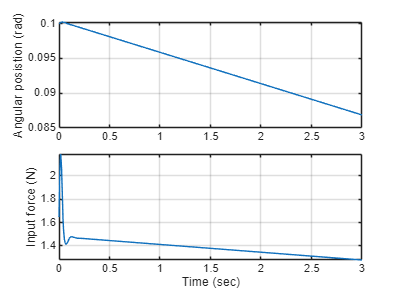

fig = figure('Position',[0 0 400 300],'Units','points');
fontname(fig,'TeXGyreTermes');
fontsize(fig,10,"points");
tiledlayout("vertical","TileSpacing","compact")

% Angular position
nexttile
plot(y,"Time (sec)","Angular posistion (rad)");
xlabel("");
% ylim([-0.05 0.15]);
legend off;
grid on;

% Input force
nexttile
plot(u,"Time (sec)","Input force (N)");
legend off;
grid on;

settingstr = "sim_"+num2str(g0)+"_"+num2str(g1)+"_"+num2str(h)+"_";
exportgraphics(fig,"figures/"+settingstr+mdlName+".svg");